# Predicting Age from Metabolomics Data

## What is metabolomics? 

**Metabolomic** data refers to the measurement of all detected metabolites from a sample (e.g. blood plasma). Metabolites that are measured include metabolic intermediates, hormones, and other signaling molecules. As metabolomics measures the level of different metabolites at a given time point, you could think of it as "a snapshot of the physiology" for that sample. 

### Methods to measure metabolomic data

Two main approaches are used to attain metabolomic data: **targeted** and **untargeted** metabolomics. The targeted approach refers to the task of measuring specific (or known) metabolites of interest. Untargeted metabolomics refers to the measurement of all molecules detected as a metabolite by the measuring platform. Several techniques can be used, including: 

- Mass spectrometry (MS): detects metabolites by their mass-to-charge (m/z) ratio; common sub-techniques include gas chromatography MS (GC-MS), liquid chromatography MS (LC-MS), and direct-injection MS (DIMS)

- Nuclear magnetic resonance (NMR) spectroscopy: detection of metabolites via magnetic fields and radio frequency pulses

- Fourier transform infrared (FT-IR) spectroscopy: metabolite detection via electromagnetic radiation

The figure below gives a visual overview of the discussed methods, as well as examples of how metabolomic data is visualized. For more information on the methods listed above, refer to [this reference](https://doi.org/10.1016/j.trac.2004.11.021).

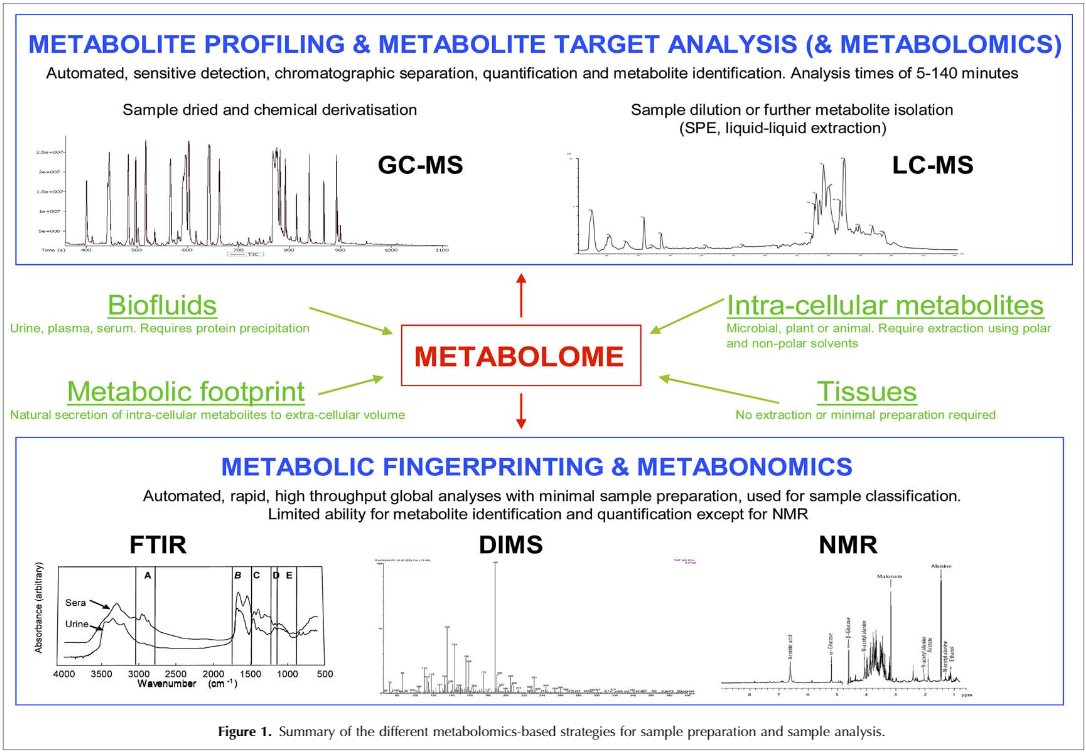

## The KarMeN study

The data that we'll be using today comes from the **Karlsruhe Metabolomics and Nutrition** (**KarMeN**) study. For [this study](https://journals.plos.org/plosone/article?id=10.1371/journal.pone.0183228), the level of different metabolites in blood plasma and urine were measured from 301 healthy individuals aged between 18-80 years old. The table below presents some of the basic characteristics of the KarMeN study participants: 

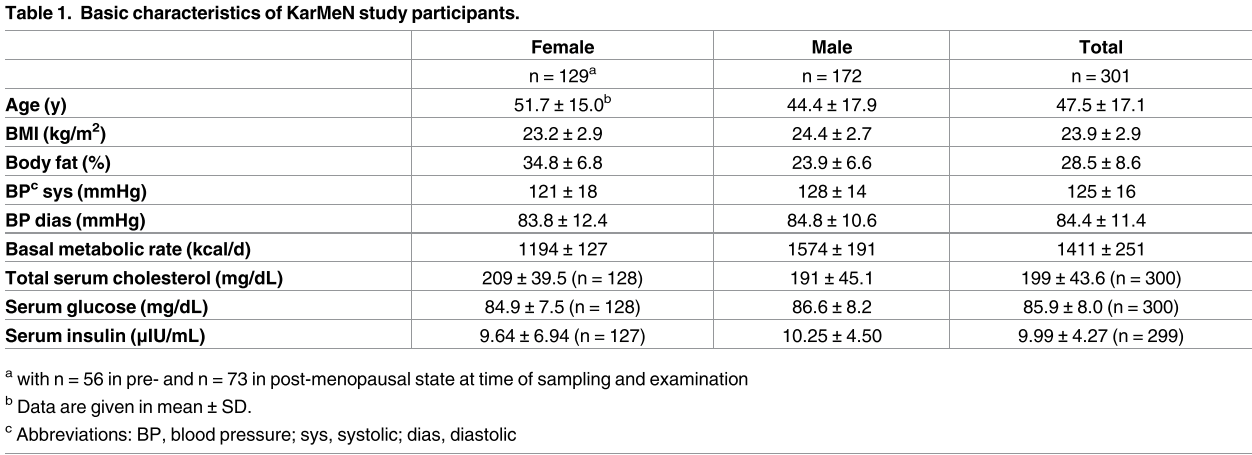

### Predicting age using decision trees and random forests

For today's lecture, we'll only work with metabolomic data measured from blood plasma samples (441 metabolites). Our main tasks will be to: 

- Predict age based on metabolomic data for male participants using DT and RF

- Predict age based on metabolomic data for female participants using DT and RF

- Compare the top 25 predictive features (i.e. metabolites) between male and female RF models

Note: the data we'll be working with today (`karmen_metabolomics.xlsx`) contains two sheets: 

- The first contains the metabolomic data as well participant age

- The second lists the full name of metabolites measured from blood plasma samples

Refer to the second sheet (`metabolite_key`) when interpreting the top predictors for RF models.

## Load and subset the data

To start, load the dataset (`karmen_metabolomics.xlsx`) as a table and display the first few entries. Then subset the table based on participant sex (create two tables, one for males and another for females):

% Load data + display top entries

% Create subset table of male participants only

% Create subset table of female participants only


## Predict age for male participants

Before building predictive models, define the input (metabolite data) and output (participant age): 

% Define input and output


We'll also use 30% holdout to train and test our models. Split the input and output based on this training/testing scheme: 

% Split data into training/testing sets via 30% holdout


### Decision tree models

Build a decision tree model using the `fitrtree` function and view the graphical structure of the tree: 

% Build DT model

% View tree structure graphically


Assess the resubstitution error and the cross-validation error of the trained model: 

% Assess the resubstitution error

% Assess the cross-validation error


Determine the best prune level based on CV error. Then build a pruned tree based on this value and view the tree structure graphically. Also assess the resubstitution and CV error for the pruned model: 

% Determine best prune level via CV error

% Build and view pruned tree

% Assess the resubstitution error

% Assess the cross-validation error


Finally, build another tree with automated hyperparameter tuning and view it graphically. Assess the resubstitution and CV error for this model as well: 

% Build and display tree with automated hyperparameter tuning

% Assess the resubstitution error

% Assess the cross-validation error


Question: How does the tree structure differ between our initial, pruned, and automated models? How do the resubstitution and CV errors compare between them?

Now, generate predictions for the test set based on all three models (initial, pruned, and automated). Also calculate the Spearman correlation between the actual output vs. the model predictions (hint: use the `corr` function and specify the `type` parameter): 

% Determine predictions using all 3 models

% Calculate the spearman correlations


Question: Which model yielded the most accurate predictions based on Spearman correlation? Subjectively, do you think this is the optimal model? Why or why not? 

### Random forests models

We'll now build random forests models using the same data we used for the DT models. Use the `TreeBagger` function to build an RF model with 200 trees (hint: specify the `method` parameter to build a regression-based model). Make sure to also set the `OOBPrediction` parameter to `on` so that we can assess the out-of-bag (OOB) error as a function of the number of trees in our model (note: include axis labels and a title): 

% Build an RF model using TreeBagger

% Determine the OOB error as trees are added 

% Plot OOB error as a function of number of trees


Question: Based on the plot above, how many trees do you think are sufficient to build an RF model using TreeBagger? 

Based on your answer above, build a new RF model and set the `OOBPredictorImportance` parameter to `on` so that we can assess which features are important for model prediction: 

% Build RF model with optimal number of trees

% Determine the top 25 important features

% Visualize importance as a bar plot for the top 25 features


Question: Which features were found to be most important? Is there any connection between these metabolites?

Now generate predictions for the test set using the model we just built. Also calculate the Spearman correlation between actual age values vs. model predictions: 

% Determine predictions for test set

% Calculate the spearman correlation


Question: How does the prediction accuracy with the RF model compare to those of the DT models? 

## Predict age for female participants

Now we'll conduct the same analysis using data for female participants. Begin by defining and splitting the inputs and output: 

% Define input and output

% Split data into training/testing sets via 30% holdout


### Decision tree models

Follow the same steps as those outlined for the male DT models: 

% Build and view initial DT model 

% Assess the resubstitution error

% Assess the cross-validation error

% Determine best prune level via CV error

% Build and view pruned model

% Assess the resubstitution error

% Assess the cross-validation error

% Build and view model with automated hyperparameter tuning

% Assess the resubstitution error

% Assess the cross-validation error


Question: How does the tree structure differ between our initial, pruned, and automated models? How do the resubstitution and CV errors compare between them?

% Determine predictions using all 3 models

% Calculate the spearman correlations


Question: Which model yielded the most accurate predictions based on Spearman correlation? Subjectively, do you think this is the optimal model? Why or why not? 

### Random forests models

Follow the same steps as those outlined for the male RF models: 

% Build an RF model using TreeBagger

% Determine the OOB error as trees are added 

% Plot OOB error as a function of number of trees

% Build RF model with optimal number of trees

% Determine the top 25 important features

% Visualize importance as a bar plot for the top 25 features


Question: Which features were found to be most important? Is there any connection between these metabolites?

% Determine predictions for test set

% Calculate the spearman correlation


Question: How does the prediction accuracy with the RF model compare to those of the DT models? 

## Compare the top 25 predictive features between RF models

Based on the top predictive features you determined for both male and female RF models, identify any overlapping entries: 

% Find any overlapping features that were important in both male and female
% RF models


Question: If there were overlapping entries, is there any connection between these metabolites? If no overlapping entries were found, why do you think this was the case? 

Question: Do the top predictors for male and female RF models make biological sense? 

## Final Comments

During today's lesson, we developed DT and RF models to predict a healthy person's age based on metabolite levels in their blood plasma. In the KarMeN study paper, the authors used other methods (SVM, glmnet, PLS) to develop their predictive models. Though these approaches differ from DT and RF, they also return which features (or metabolites) were most predictive of participant age. The figure below shows the top features determined from the models discussed in their paper: 

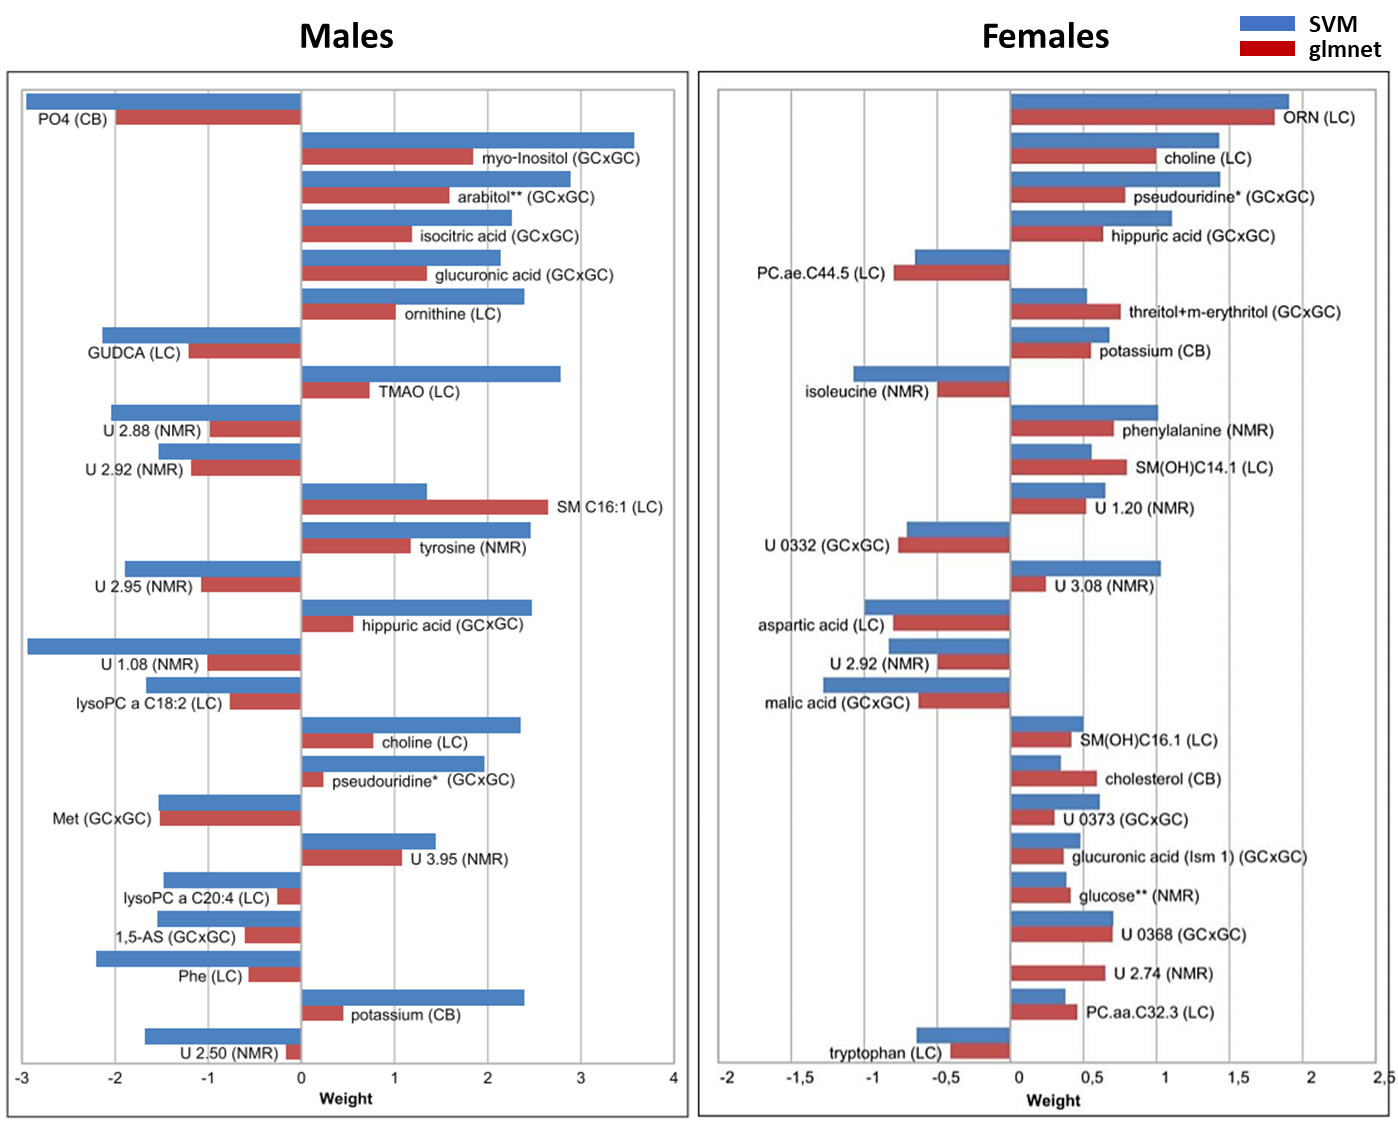

Comparing the top predictors for your RF models, did any coincide with those presented by the authors?

### Metabolomics and ML for clinical applications

As metabolomic data is indicative of the physiological state of a cell, tissue, or sample, many research efforts are focused on applying this data for diagnostic and clinical purposes. Some highly researched areas include cancer, diabetes, and cardiovascular/metabolic diseases. As the application of machine learning is also relatively new in biomedical research, there remains a lot of room for medical discovery and advancement through ML-based analysis of high-throughput data.

## References

- [Dunn & Ellis (2005)](https://doi.org/10.1016/j.trac.2004.11.021) - review of methodologies used for metabolomics research

- [Rist et al. (2017)](https://journals.plos.org/plosone/article?id=10.1371/journal.pone.0183228) - KarMeN study paper

- [Collino, Martin & Rezzi (2012)](https://bpspubs.onlinelibrary.wiley.com/doi/full/10.1111/j.1365-2125.2012.04216.x) - additional reading on metabolomics for clinical applications